folderpath = fullfile(pwd,"EECE5554/LAB3/src/")

folderpath = "/home/qianw/EECE5554/LAB3/src/"

%folderpath = fullfile(pwd,"imu_interface/IMUmsg")
ros2genmsg(folderpath)

Identifying message files in folder '/home/qianw/EECE5554/LAB3/src'.Validating message files in folder '/home/qianw/EECE5554/LAB3/src'.Done.
Done.
[1/1] Generating MATLAB interfaces for custom message packages... Done.
Running colcon build in folder '/home/qianw/EECE5554/LAB3/src/matlab_msg_gen/glnxa64'.
Build in progress. This may take several minutes...
Build succeeded.build_log.

%ros2 msg list q

bagselect2=ros2bagreader("EECE5554/LAB3/src/data/rosbag2_moving/")

bagselect2 =   ros2bagreader with properties:

           FilePath: '/home/qianw/EECE5554/LAB3/src/data/rosbag2_moving'
      AvailableBags: "rosbag2_moving.db3"
          StartTime: 1.7417e+09
            EndTime: 1.7417e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [13018×3 table]
        NumMessages: 13018


## STATIONARY


% a. Gyro, X, Y, Z
% b. Accelerometer, X, Y, Z
% c. Magnetometer, X, Y, Z
% d. Orientation (Euler angles), X, Y, Z
% e. Calculate the mean and median the orientation time series data and use a series of
% histograms (X, Y, Z) to plot the sensor output distribution around the median. What
% type of distribution(s) to you get?

msgStructs = readMessages(bagselect2);
bSel = select(bagselect2,'Topic','/imu');
%imu = readMessages(bSel,'DataFormat','struct');
msgStructs{1}

ans = struct with fields:
    MessageType: 'imu_interface/IMUmsg'
         header: [1×1 struct]
            imu: [1×1 struct]
      mag_field: [1×1 struct]
         rawstr: '$VNYMR,-049.131,+002.031,-000.278,-00.0032,-00.0024,+00.0093,+00.340,+00.064,-09.391,+00.001368,+00.001685,-00.002569*69'


gyroPoints = cellfun(@(m) struct(m.imu.angular_velocity),msgStructs)

gyroPoints = 13018×1 struct array with fields:
    MessageType
    x
    y
    z


accelPoints = cellfun(@(m) struct(m.imu.linear_acceleration),msgStructs);
orientPoints = cellfun(@(m) struct(m.imu.orientation),msgStructs);
magPoints = cellfun(@(m) struct(m.mag_field.magnetic_field),msgStructs);


VNYMR = cellfun(@(m) string(m.rawstr),msgStructs)

VNYMR = 13018×1 string array
    "$VNYMR,-049.131,+002.031,-000.278,-00.0032,-00.0024,+00.0093,+00.340,+00.064,-09.391,+00.001368,+00.001685,-00.002569*69"
    "$VNYMR,-049.134,+002.030,-000.278,-00.0032,-00.0024,+00.0093,+00.310,+00.048,-09.397,+00.000924,-00.000163,-00.002386*6C"
    "$VNYMR,-049.136,+002.028,-000.280,-00.0032,-00.0022,+00.0094,+00.335,+00.060,-09.362,+00.000467,-00.001194,-00.001772*69"
    "$VNYMR,-049.140,+002.028,-000.279,-00.0032,-00.0022,+00.0093,+00.361,+00.060,-09.371,-00.000997,-00.001073,-00.002524*64"
    "$VNYMR,-049.142,+002.030,-000.279,-00.0032,-00.0022,+00.0093,+00.343,+00.058,-09.382,+00.000370,+00.001818,-00.001299*6C"
    "$VNYMR,-049.145,+002.031,-000.280,-00.0031,-00.0022,+00.0094,+00.326,+00.049,-09.347,+00.000884,+00.001552,-00.002202*60"
    "$VNYMR,-049.148,+002.031,-000.281,-00.0030,-00.0020,+00.0093,+00.295,+00.040,-09.384,-00.000658,-00.001060,-00.001589*6B"
    "$VNYMR,-049.151,+002.030,-000.279,-00.0031,-00.0021,+00.0093,+00.325,+00.063,

%plot(imuPoints)

%gyroData = gyroPoints{:,[2 3 4]}
gyroPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              x: 0.0014
              y: 0.0017
              z: -0.0026


xGyro = arrayfun(@(m) double(m.x),gyroPoints);
yGyro = arrayfun(@(m) double(m.y),gyroPoints);
zGyro = arrayfun(@(m) double(m.z),gyroPoints);


accelPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              x: 0.3400
              y: 0.0640
              z: -9.3910


xAccel = arrayfun(@(m) double(m.x),accelPoints);
yAccel = arrayfun(@(m) double(m.y),accelPoints);
zAccel = arrayfun(@(m) double(m.z),accelPoints);

orientPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Quaternion'
              x: -0.2780
              y: 2.0310
              z: -49.1310
              w: 1


xOrient = arrayfun(@(m) double(m.x),orientPoints);
yOrient = arrayfun(@(m) double(m.y),orientPoints);
zOrient = arrayfun(@(m) double(m.z),orientPoints);
wOrient = arrayfun(@(m) double(m.w),orientPoints);

magPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              x: -0.0032
              y: -0.0024
              z: 0.0093


xMag = arrayfun(@(m) double(m.x),magPoints);
yMag = arrayfun(@(m) double(m.y),magPoints);
zMag = arrayfun(@(m) double(m.z),magPoints);

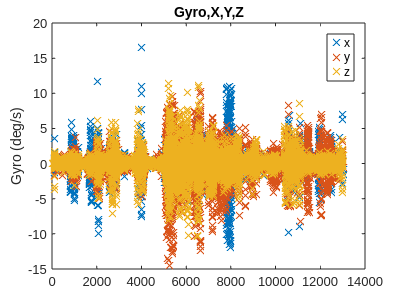

figure
plot(xGyro,'x')
hold on
plot(yGyro,'x')
plot(zGyro,'x')
title('Gyro,X,Y,Z')
%xlabel('Time')
ylabel('Gyro (deg/s)')
legend('x','y','z')
saveas(gcf,'MovingGyroplot.png')

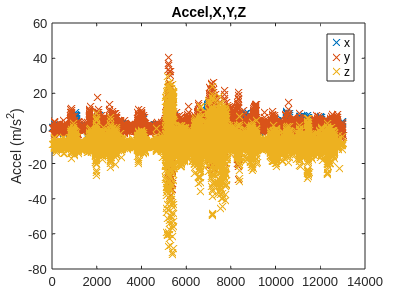


figure
plot(xAccel,'x')
hold on
plot(yAccel,'x')
plot(zAccel,'x')
title('Accel,X,Y,Z')
%xlabel('Time') 
ylabel('Accel (m/s^2)')
legend('x','y','z')
saveas(gcf,'MovingAccelplot.png')

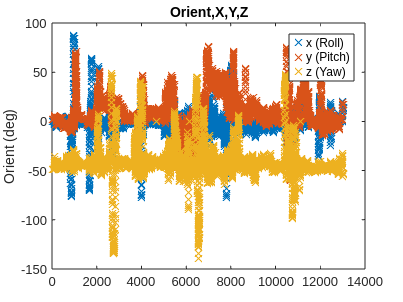


figure
plot(xOrient,'x')
hold on
plot(yOrient,'x')
plot(zOrient,'x')
title('Orient,X,Y,Z')
%xlabel('Time')
ylabel('Orient (deg)')
legend('x (Roll)','y (Pitch)','z (Yaw)')
saveas(gcf,'MovingOrientplot.png')

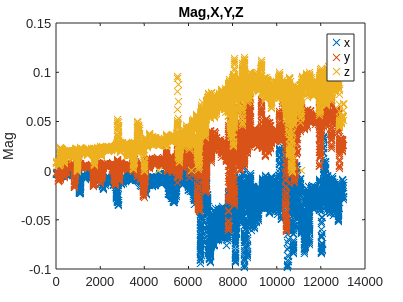


figure
plot(xMag,'x')
hold on
plot(yMag,'x')
plot(zMag,'x')
title('Mag,X,Y,Z')
%xlabel('Time')
ylabel('Mag')
legend('x','y','z')
saveas(gcf,'MovingMagplot.png')

%ORIENTATION
mean_x = mean(xOrient)

mean_x = -2.6949

dataMeanx = mean(xOrient(:));
mean_y = mean(yOrient)

mean_y = 8.0346

dataMeany = mean(yOrient(:));
mean_z = mean(zOrient)

mean_z = -41.5801

dataMeanx = mean(xOrient(:));

median_x = median(xOrient)

median_x = -2.3060

dataMedianx = median(xOrient(:));
median_y = median(yOrient)

median_y = 4.8710

dataMediany = median(yOrient(:));
median_z = median(zOrient)

median_z = -43.9720

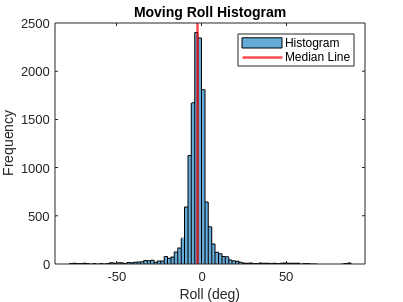

dataMedianz = median(zOrient(:));

figure
histogram(xOrient)
hold on
xline(dataMedianx, 'Color', 'r', 'LineWidth', 2);
title('Moving Roll Histogram')
ylabel('Frequency')
xlabel('Roll (deg)')
legend('Histogram','Median Line')
saveas(gcf,'MovingHistogramRoll.png')

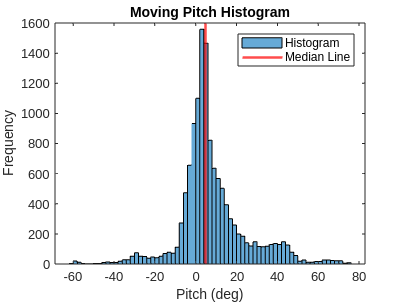


figure
histogram(yOrient)
hold on
xline(dataMediany, 'Color', 'r', 'LineWidth', 2);
title('Moving Pitch Histogram')
ylabel('Frequency')
xlabel('Pitch (deg)')
legend('Histogram','Median Line')
saveas(gcf,'MovingHistogramPitch.png')

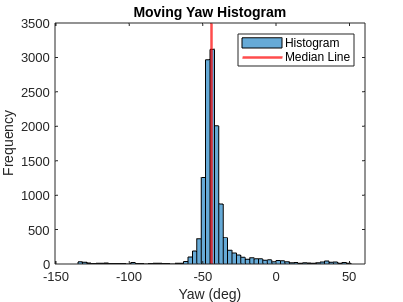


figure
histogram(zOrient)
hold on
xline(dataMedianz, 'Color', 'r', 'LineWidth', 2);
title('Moving Yaw Histogram')
ylabel('Frequency')
xlabel('Yaw (deg)')
legend('Histogram','Median Line')
saveas(gcf,'MovingHistogramYaw.png')